Addpath

clear;clc;
close all

Sampling Time, Time Step & Simulation Time

dt=1e-4;
ts=0.31;
SimulationTime=10;
TimeSpan=0:dt:SimulationTime;

Initial Condition

StateInitial=[0.5;0];

PD Gains

kp=1;
kd=0.5;

Time History Matrix for Digital Case

DigitalStateTimeHistory=zeros(2,round(SimulationTime/dt)+1);
DigitalSampledStateTimeHistory=zeros(2,floor(SimulationTime/ts));
DigitalTorqueTimeHistory=zeros(1,round(SimulationTime/dt)+1);
DigitalStateTimeHistory(:,1)=StateInitial;
DigitalSampledStateTimeHistory(:,1)=StateInitial;
DigitalTorqueTimeHistory(:,1)=PDController(DigitalSampledStateTimeHistory(:,1),kp,kd);

ODE Solver Option

ODEOption=odeset('RelTol', 1e-6, 'AbsTol', 1e-6);

Simulation

bar=waitbar(0,"Start Simulation");
for i=1:floor(SimulationTime/ts)
    DigitalSampledStateTimeHistory(:,i)=DigitalStateTimeHistory(:,(i-1)*round(ts/dt)+1);
    if i==1
        Tau=PDController(DigitalSampledStateTimeHistory(:,1),kp,kd);
    else
        Tau=PDController(DigitalSampledStateTimeHistory(:,i-1),kp,kd);
    end
    DigitalTorqueTimeHistory(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=repmat(Tau,1,round(ts/dt));
    [t,State]=ode45(@(t,State)SingleDoFDyn_ODE(t,State,Tau),TimeSpan((i-1)*round(ts/dt)+1:i*round(ts/dt)+1),DigitalStateTimeHistory(:,(i-1)*round(ts/dt)+1),ODEOption);
    DigitalStateTimeHistory(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=State(2:end,:)';
    str=[num2str(100*i/floor(SimulationTime/ts)),'%',' Finished'];
    waitbar(i/floor(SimulationTime/ts),bar,str);
end
waitbar(1,bar,"Handling Final Interval");
if floor(SimulationTime/ts)~=ceil(SimulationTime/ts)
    [t,State]=ode45(@(t,State)SingleDoFDyn_ODE(t,State,Tau),TimeSpan(floor(SimulationTime/ts)*round(ts/dt)+1:end),DigitalStateTimeHistory(:,floor(SimulationTime/ts)*round(ts/dt)+1),ODEOption);
    DigitalStateTimeHistory(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=State(2:end,:)';
    DigitalTorqueTimeHistory(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=repmat(Tau,1,round(mod(SimulationTime,ts)/dt));
end
delete(bar);

$0$th Order Expansion

DDE Setups

Controller=@(State)PDController(State,kp,kd);

DDE Solver Option

tic
DDEOption=ddeset('RelTol', 1e-6, 'AbsTol', 1e-6,"InitialStep",dt,"MaxStep",1.5*dt);
sol_Order0=dde23(@(t,State,StateDelayed)SingleDoFDyn_DDE(t,State,StateDelayed,Controller), ...
    1.5*ts,StateInitial,TimeSpan,DDEOption);
toc

历时 47.693162 秒。


Show Time Steps

disp("Simulation time steps: "+num2str(length(sol_Order0.x)))

Simulation time steps: 66670


disp("Visualization time steps: "+num2str(length(TimeSpan)))

Visualization time steps: 100001


Collect Data for Visualization

DelayStateTimeHistory_Order0=deval(sol_Order0,TimeSpan,1:2);

$2$nd Order Expansion

DDE Solver Option

solver="ddesd"

solver = "ddesd"

tic
if solver=="ddesd"
    sol_Order2=ddesd(@(t,State,StateDelayed)SingleDoFDyn_DDE(t,State,StateDelayed,Controller), ...
    DelayTruncation(t,ts,2),StateInitial,TimeSpan,DDEOption);
end
if solver=="ddensd"
   sol_Order2=ddensd(@(t,State,StateDelayed,StatePrimeDelayed)SingleDoFDyn_DDEnsd(t,State,StateDelayed,StatePrimeDelayed,Controller), ...
    DelayTruncation(t,ts,2),t,StateInitial,TimeSpan,DDEOption); 
end
toc

历时 11141.834727 秒。


Show Time Steps

disp("Simulation time steps: "+num2str(length(sol_Order2.x)))

Simulation time steps: 66669


disp("Visualization time steps: "+num2str(length(TimeSpan)))

Visualization time steps: 100001


Collect Data for Visualization

DelayStateTimeHistory_Order2=deval(sol_Order2,TimeSpan,1:2);

$x-t$ Diagram

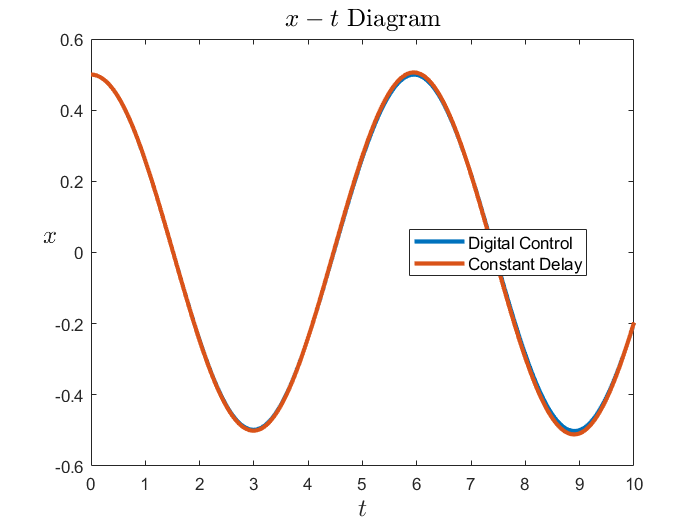

plot(TimeSpan,DigitalStateTimeHistory(1,:),"LineWidth",2.5);
hold on
plot(TimeSpan,DelayStateTimeHistory_Order0(1,:),"LineWidth",2.5);
hold off
title("$$x-t$$ Diagram","FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$x$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Digital Control","Constant Delay","Fontsize",10,"Location","best")

$\dot{x}-t$ Diagram

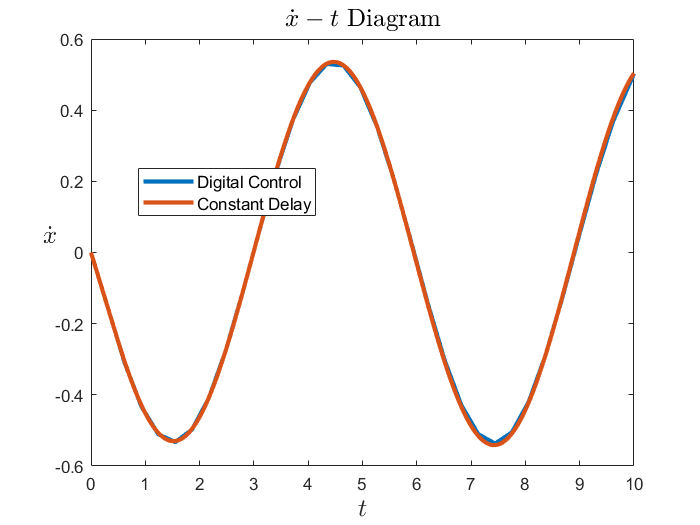

plot(TimeSpan,DigitalStateTimeHistory(2,:),"LineWidth",2.5);
hold on
plot(TimeSpan,DelayStateTimeHistory_Order0(2,:),"LineWidth",2.5);
hold off
title("$$\dot{x}-t$$ Diagram","FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{x}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Digital Control","Constant Delay","Fontsize",10,"Location","best")

Phase Portrait

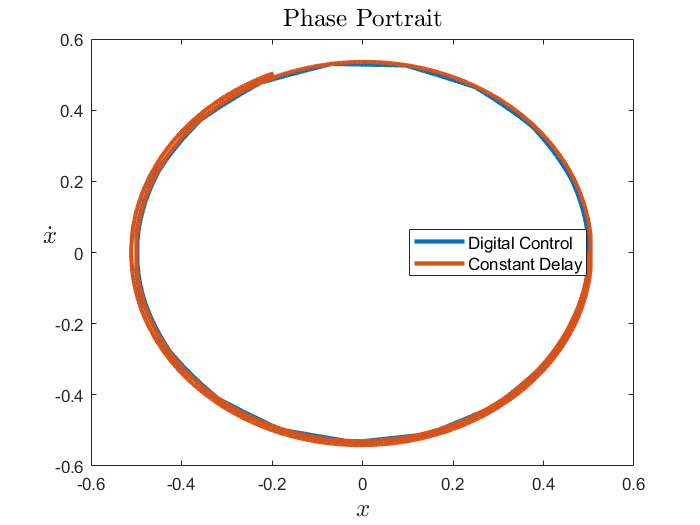

plot(DigitalStateTimeHistory(1,:),DigitalStateTimeHistory(2,:),"LineWidth",2.5);
hold on
plot(DelayStateTimeHistory_Order0(1,:),DelayStateTimeHistory_Order0(2,:),"LineWidth",2.5);
hold off
title("Phase Portrait","FontSize",15,"Interpreter","latex")
xlabel("$$x$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{x}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Digital Control","Constant Delay","Fontsize",10,"Location","best")

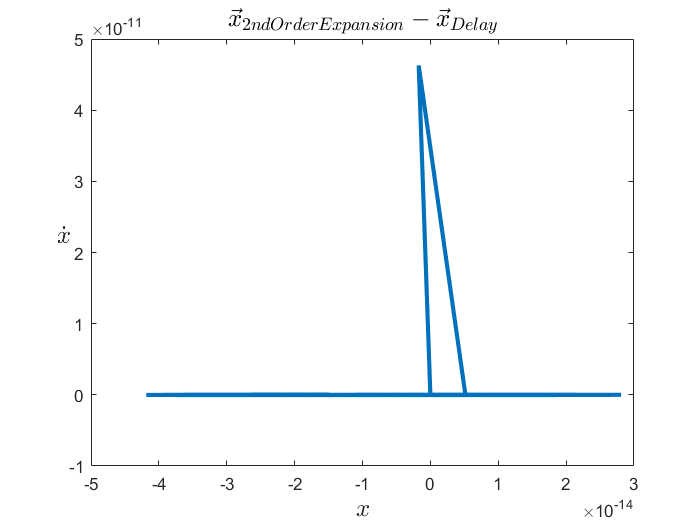

plot(DelayStateTimeHistory_Order2(1,:)-DelayStateTimeHistory_Order0(1,:), ...
    DelayStateTimeHistory_Order2(2,:)-DelayStateTimeHistory_Order0(2,:),"LineWidth",2.5)
title("$$\vec{x}_{2nd Order Expansion}-\vec{x}_{Delay}$$","FontSize",15,"Interpreter","latex")
xlabel("$$x$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{x}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")

PD Controller

function Tau=PDController(State,kp,kd)
    Tau=-kp*State(1)-kd*State(2);
end

Time Varying Delay

function td=DelayTruncation(t,ts,n_expansion)
    td=3/2*ts;
    for i=1:n_expansion
        td=td-ts/(i*pi)*sin(2*i*pi*t/ts);
    end
end

ODE of Dynamics

function dState=SingleDoFDyn_ODE(t,State,Input)
    v=State(2);
    a=Input;
    dState=[v;a];
end

DDE of Dynamics

function dState=SingleDoFDyn_DDE(t,State,StateDelayed,Controller)
    dState=[State(2);Controller(StateDelayed)];
end

DDE for `ddensd`

function dState=SingleDoFDyn_DDEnsd(t,State,StateDelayed,StatePrimeDelayed,Controller)
    dState=[State(2);Controller(StateDelayed)];
end